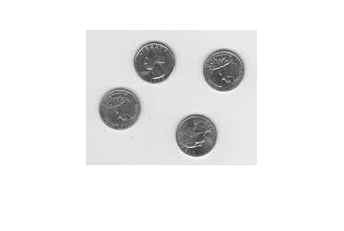

img = rgb2gray(imread('eight.tif'));
imshow(img);

[r,c] = size(img);

newImg = uint8(zeros(r,c));
for i = 2:r-1
    for j = 2:c-1
        total = 0;
        for x = i-1:i+1
            for y = j-1:j+1
                total = total+double(img(x,y));
            end
        end
        newImg(i,j) = total/9;
    end
end

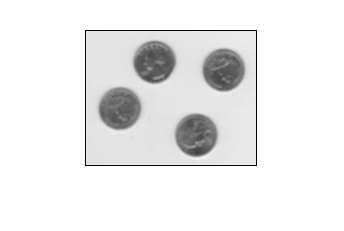

imshow(newImg);